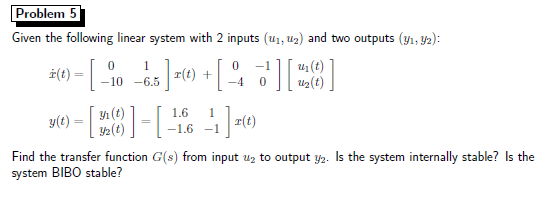

A=[0 1;-10 -6.5];
B=[0 -1;-4 0]';
C=[1.6 1;-1.6 -1];
D=[0];

sys=ss(A,B,C,D);
% step(sys)
s=tf('s');

H=tf(sys)

H =
 
  From input 1 to output...
           -s - 1.6
   1:  ----------------
       s^2 + 6.5 s + 10
 
           s + 1.6
   2:  ----------------
       s^2 + 6.5 s + 10
 
  From input 2 to output...
         -6.4 s - 1.6
   1:  ----------------
       s^2 + 6.5 s + 10
 
         6.4 s + 1.6
   2:  ----------------
       s^2 + 6.5 s + 10
 
Continuous-time transfer function.



minreal(zpk(H),1e-3)

ans =
 
  From input 1 to output...
         - (s+1.6)
   1:  -------------
       (s+4) (s+2.5)
 
          (s+1.6)
   2:  -------------
       (s+4) (s+2.5)
 
  From input 2 to output...
       -6.4 (s+0.25)
   1:  -------------
       (s+4) (s+2.5)
 
       6.4 (s+0.25)
   2:  -------------
       (s+4) (s+2.5)
 
Continuous-time zero/pole/gain model.



pole(H(2,2))

ans =    -4.0000
   -2.5000


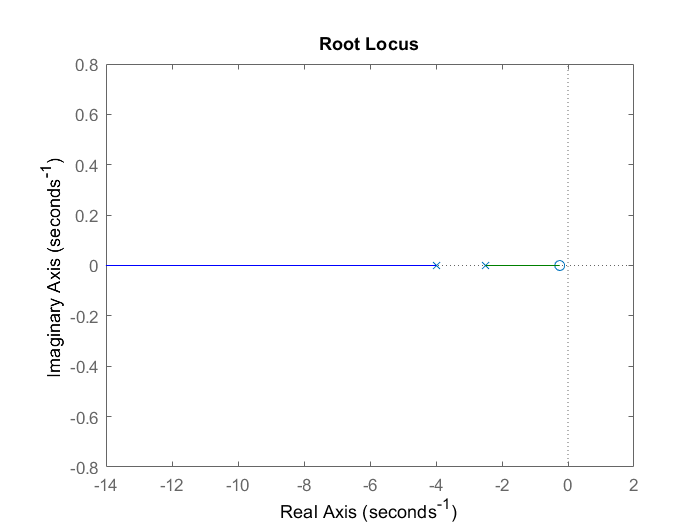

rlocus(H(2,2))

All the eigenvalues are negative and both with molteplicity =2 so the system is asintotically stable.

$$H = \frac{6\,s-\frac{8}{5}}{s^{2}-\frac{13\,s}{2}+10}$$

$$f(t) = 2$$

$$y = \frac{112\,{\mathrm{e}}^{4\,t}}{15}-\frac{536\,{\mathrm{e}}^{\frac{5\,t}{2}}}{75}-\frac{8}{25}$$

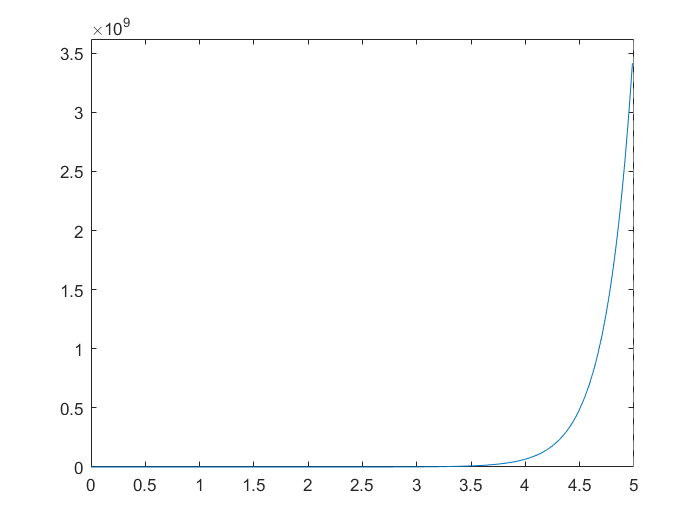

% simulink
% sim("ex6.slx")